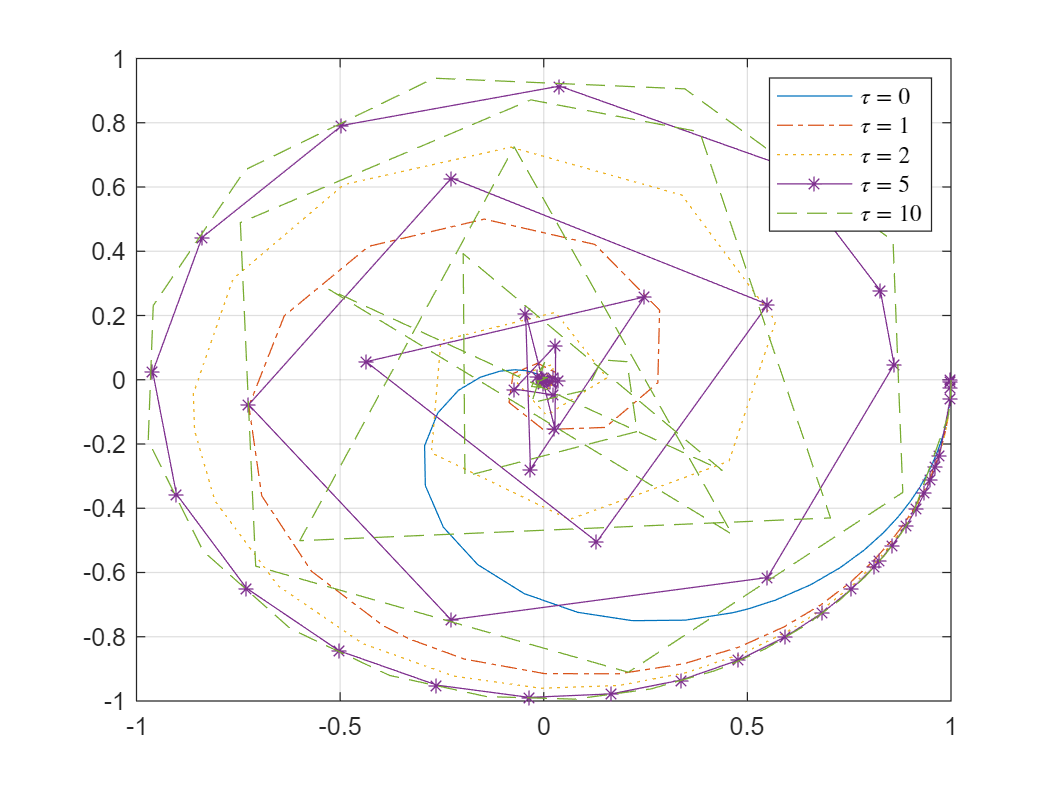

clear all;
close all;
clc;

s = tf('s');
P1 = 20.5/((s+2)*(s^2+5*s+10.25));
[re1,im1,w1]=nyquist(P1);

 
P2 = exp(-1*s)*20.5/((s+2)*(s^2+5*s+10.25));
[re2,im2,w2]=nyquist(P2);
 
P3 = exp(-2*s)*20.5/((s+2)*(s^2+5*s+10.25));
[re3,im3,w3]=nyquist(P3);
 
P4 = exp(-5*s)*20.5/((s+2)*(s^2+5*s+10.25));
[re4,im4,w4]=nyquist(P4);
 
P5 = exp(-10*s)*20.5/((s+2)*(s^2+5*s+10.25));
[re5,im5,w5]=nyquist(P5);
 
plot(squeeze(re1),squeeze(im1),'-', ...
     squeeze(re2),squeeze(im2),'-.', ...
     squeeze(re3),squeeze(im3),':', ...
     squeeze(re4),squeeze(im4),'-*', ...
     squeeze(re5),squeeze(im5),'--' ...
     );
grid on;
hh = legend('$\tau=0$','$\tau=1$','$\tau=2$','$\tau=5$','$\tau=10$');
set(hh,'Interpreter','latex'); 

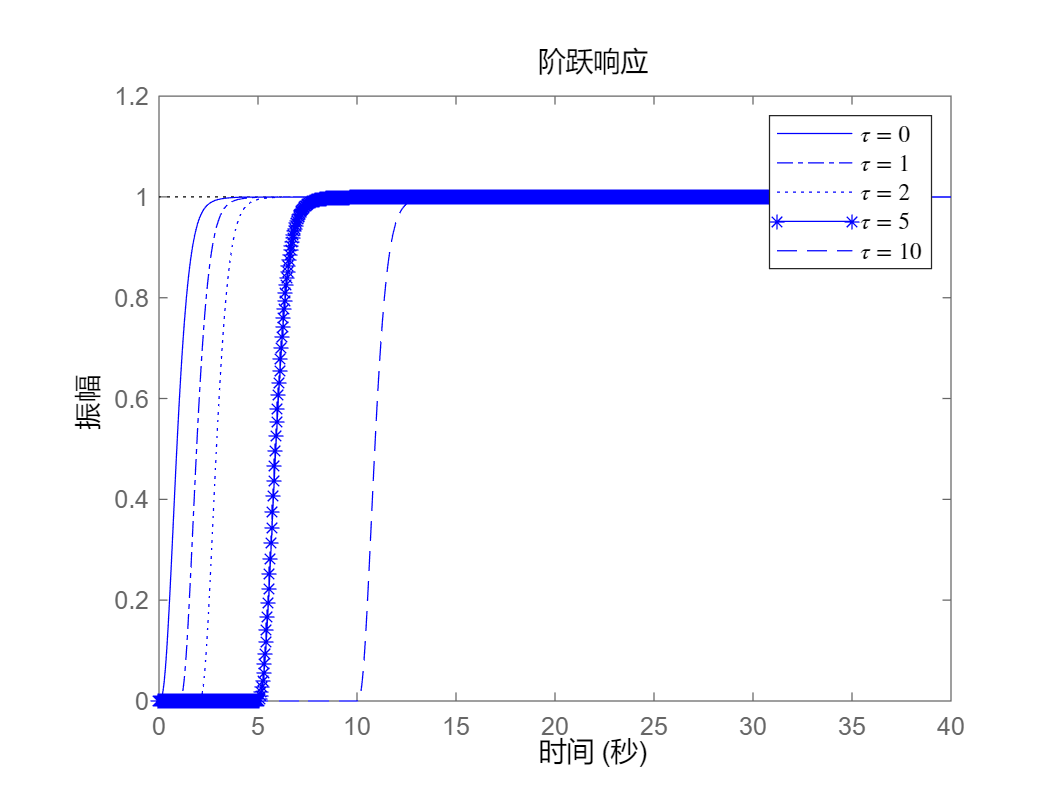


step(P1,'-',P2,'-.',P3,':',P4,'-*',P5,'--');
hh = legend('$\tau=0$','$\tau=1$','$\tau=2$','$\tau=5$','$\tau=10$');
set(hh,'Interpreter','latex'); 